# **Least Squares**

# Introduction

Let $S$ be a symmetric matrix. Since $S$ is a square matrix (why?), it has an $\textrm{LU}$ decomposition. In fact, the symmetry makes it possible to write $S$ in the form $S={\textrm{LL}}^T$, where $L$ is a lower-triangular matrix. This is called the *Cholesky decomposition* of $S$, and it is defined only for symmetric matrices. Given a symmetric matrix, the Cholesky decomposition is always preferable in computations because it can be computed in half the time of the $\textrm{LU}$ decomposition.

There is nothing special about writing the Cholesky decomposition in terms of a lower-triangular matrix. We can just as well write $S={\textrm{UU}}^T$, where $U=L^T$. In MATLAB, the command 

returns the Cholesky decomposition of the symmetric matrix $S$ in the upper -triangular matrix $U$. Once the Cholesky decomposition $S=U^T U$ is found, solving a system of the form 


$$S\mathbf{c} = \mathbf{z}$$


proceeds in the same 2-step manner as solving $A\mathbf{x} = \mathbf{b}$ with the LU decomposition.

- Solve $U^T\mathbf{w} = \mathbf{z}$

- Solve $U\mathbf{c} = \mathbf{w}$

# The normal equations for the least squares

Suppose we are given a collection of data points of the form ${\left\lbrace \left(x_i ,y_i \right)\right\rbrace }_{i=1}^n$,which are observed values of some quantities $x$ and $y$ (for example, some physical, or any other quantities). The simplest possible relation between $x$ and $y$ is linear: $y=c_1 +c_2 x$, where $c_1$ and $c_2$ are some unknown constant coefficients (yet to be determined). However, due to error in measurement (imperfect device, imperfect conditions of measuring, causing inevitable noise), the above theoretical relation is hardly ever achieved. Instead, the true relation between observed quantities $x$ and $y$ is of the form

                                                                   $y=c_1 +c_{2\;} x+\varepsilon$                                                                              (1)

where $\epsilon$ is the random error, or "noise" - that is, the amount by which $c_1 +c_2 x$ fails to coincide with $y$. Applying our model represented by the equation (1) to the data points, we have:

                                                                    $y_i =c_1 +c_{2\;} x_i +\varepsilon_i$                                                                      (2)

Our model just states that the relation is linear (plus the error term), but does not say anyting about the values of the constants  $c_1$ and $c_2$. For the same set of data ${\left\lbrace \left(x_i ,y_i \right)\right\rbrace }_{i=1}^n$, different choices of $c_1$ and $c_2$ give different errors (residuals) $\epsilon_i \ldotp \;$It is our taks to find most plausible estimates of $c_1$ and $c_2$ based on the observed data. Although MATLAB provides an entire toolbox for statistical analysis, we will use only a few simple commands to get started; the pedagogical purpose is to make sure that you understand how the problem is set up mathematically.

Equation (2) can be extended to any polynomial model. For example, if we suppose that 

                                                        $y_i =c_1 +c_{2\;} x_i +c_3 x_i^2 +\dots +c_p x_i^{p-1} +\varepsilon_i$                                                    (3)

then we have to estimate the $p$ unknonws $c_{1,} c_2 ,\dots ,c_p$ so that $\varepsilon_i$ is small for all $i$. Statisticians write the estimation problem in the following form:

                                                                               $\mathbf{y}=X\mathbf{c} + \epsilon$                                                                         (4)

where $\mathbf{y} = ( y_1, y_2, \ldots, y_n)^T$ is an $n$-vector of observations (i.e., the dependent variable), $\mathbf{c} = ( c_1, c_2, \ldots, c_p)^T$is the $p$-vector of unknown parameters, $X$ is the $n\times p$ matrix


$$X=\left[\begin{array}{ccccc} 1 & x_1 & x_1^2 &\ldots &x_1^{p-1}  \\
1 & x_2 & x_2^2 &\ldots &x_2^{p-1} \\
\vdots&\ddots &\vdots &&\\
1 & x_n & x_n^2 &\ldots &x_n^{p-1} 
\end{array}\right]$$


and $\mathbf{\epsilon} = ( \epsilon_1, \epsilon_2, \ldots, \epsilon_n)^T$ is the vector of residuals corresponding to $n$ observations. It is straighforward to verify that the $i$th row of the matrix-vector product (4), plus the $i$th component of $\varepsilon$, yields the right hand side of (3).

The least squares solution of (4) is the solution $\hat{\mathbf{c}}$ of the *Normal Equations*:

                                                                                   $X^TX\mathbf{c}=X^T\mathbf{y}$                                                                        (5)

The vector $\hat{\mathbf{c}}$ minimizes the quantity $\| \epsilon\| = \| \mathbf{y}- X \mathbf{c}\|$, that is, minimizes the difference between the sum of the squares of the differences between the "predicted" value of $\mathbf{y}$ from the "observed" value of $\mathbf{y}$, where the sum is taken over every point in the dataset. 

Notice that $X^T X$ is a symmetric matrix.

The system (5) can be solved as follows:

- Define $\mathbf{z} = X^T \mathbf{y}$

- Define $S=X^TX$

- Solve $S\mathbf{c} = \mathbf{z}$

The last step must be performed using the Cholesky decomposition of $S$ and solving the two triangular systems.

# MATLAB Notes

- Transposition is denoted by prime (i.e. a single quotation mark): $X^T$ is denoted by `X'` .

- The triangular system obtained from the Cholesky decomposition must be solved using teh MATLAB "backslash" command. For example, to solve $U^T \mathbf{w} = \mathbf{z},$ type w`=U'\z`.

- Given the vector $\mathbf{a} = \left[ a_1, a_2, \ldots, a_n\right]^T$, you can form the vector $ \left[ a_1^2, a_2^2, \ldots, a_n^2\right]^T$with the expression `a.^2 `(component-wise exponentiation).

- When building the matrix $X$ you should use the special matrix `ones` .

# Example 1: Lest Squares Fit to a Data Set by a Linear Function

Compute the coefficients of the best linear least-squares fit ,$y=c_1 +c_2 x\;,\;$to the following data:


$$\begin{array}{c|cccccc} x &\vert & 2.4 & 3.6 &3.6 & 4.1 & 4.7 & 5.3 \\ \hline y &\vert & 33.8 & 34.7 & 35.5 & 36.0 & 37.5 & 38.1 \end{array}$$


Plot both the linear function and the data points on the same axis system.

**Solution:**

We can solve the problem with the following MATLAB commands

x=[2.4; 3.6; 3.6; 4.1; 4.7; 5.3];  % build column vector of x-values
y=[33.8; 34.7; 35.5; 36.0; 37.5; 38.1]; % build column vector of y-values
X=[ones(size(x)),x]; % build the matrix X for the linear model
z=X'*y;      % right hand side of the Normal Equations
S=X'*X;      % Left hand sid of the Normal Equations
U=chol(S);   % Cholesky decomposition
w=U'\z;      % solve the normal equations using Cholesky decomposition
c=U\w        % compute the coefficients of the linear fit

c =    29.6821
    1.5826


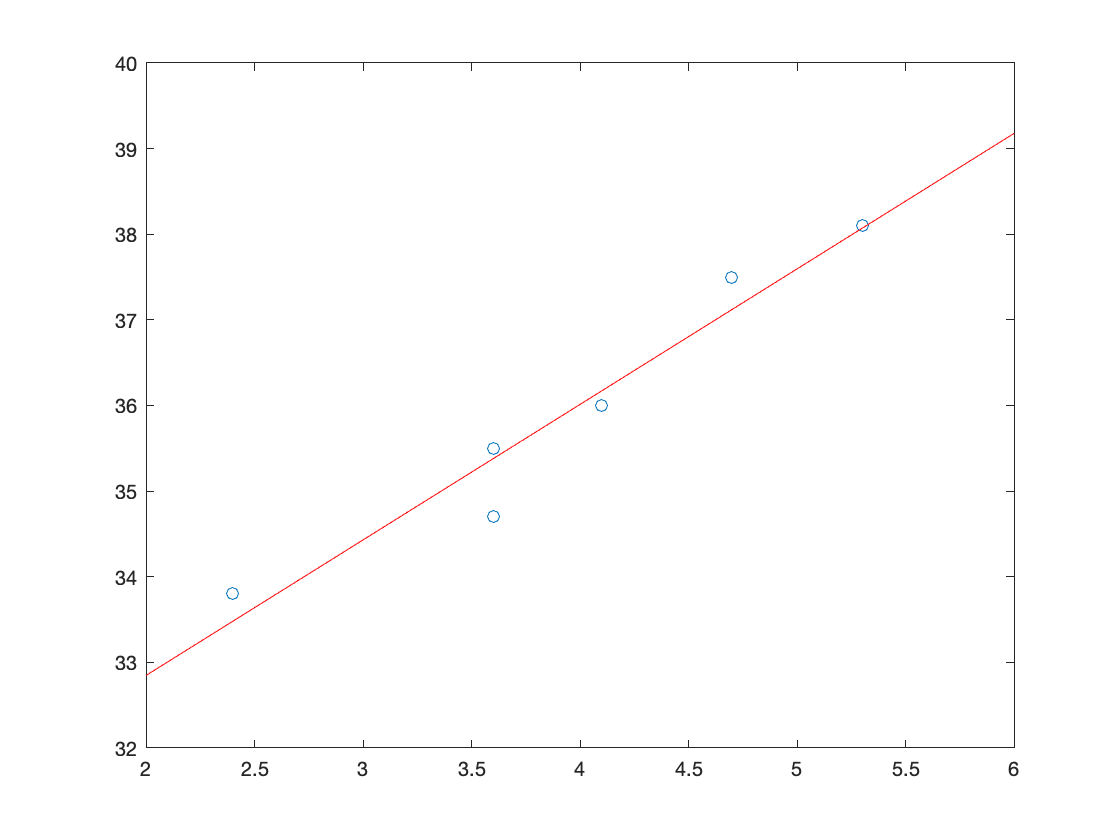

plot(x,y,'o');  % plot the data points
q=2:0.1:6;   % define a vector for plotting the linear fit 
             % the vector q is chosen so that it covers the whole range of x-values
fit=c(1)+c(2)*q;   % define the linear fit
hold on % hold the figure so that fit and data points are plotted together
plot(q,fit,'r')   %plot the linear fit together with the data points

Note that we did not suppress the output in the line that computes the values of `c`, so that they are displayed when running the code. The best linear fit has equation $y=29\ldotp 6821+1\ldotp 5826\;x$